# Make a Recommendation About the Effectiveness of OptiNStim, A Visual Prosthesis, Using Hypothesis Testing

Gati Aher | Neurotechnology: Brains and Machines (ENGR3635) | April 26, 2021

## Introduction

This analysis aims to model the factors that impact the results of using a fictional prosthesis OptiNStim, and make a recommendation for a fictional patient.

Effectiveness of treatment is measured by pixel improvement (measured in pixels) of subject accuracy on a white square touch test when using OptiNStim compared to not using OptiNStim.

This analysis will:

- Determine if age group (child or adult) has an effect on pixel improvement

- Determine if stimulus configuration (feedback or no-feedback) has an effect on pixel improvement

- Determine if there is an interaction between stimulation configuration and age group for accuracy change in pixel improvement when given the OptiNStim treatment.

As the experiment has a quantitative outcome (Pixels) and two nominal variables (Age and Stimulation), the most appropriate test is **Two-Way ANOVA**. This test compares the mean differences between groups that have been split on two factors, and its primary purpose is to understand if there is an interaction between the two factors variables on the outcome.

An F-statistic will be computed for each hypothesis and evaluated at **alpha = 0.05**

#### Null Hypotheses:

- **H0_1:** Age has no significant equal mean pixel improvement

- **H0_2:** Stimulus Configuration has no significant effect on pixel improvement

- **H0_3:** The factors are independent (the interaction between age and stimulus configuration has no significant effect on pixel improvement)

Because I am evaluating multiple hypotheses simultaneously, I have a certain probability of observing at least one significant result just due to chance.

P_at_least_one_sig_result = 1 - (1 - 0.05)^2

P_at_least_one_sig_result = 0.0975

So with 2 tests being considered, there is a 9.75% chance of observing at least one significant result, even if all the tests are actually not significant. Therefore, I use the **Bonferroni correction** to set the significance cut-off at **alpha/n = 0.025** for each test. This corrected alpha tends to be conservative, leading to a high rate of false negatives.

corrected_alpha = 0.05/2

corrected_alpha = 0.0250

A eta squared test will be used to estimate effect sizes of statistically significant values.

Other tests will be used to test that the data follows assumptions for Two-Way ANOVA testing.

## Case Study: Background Information on OptiNStim:

This fictional scenario is loosely based on Gaillet, V., Cutrone, A., Artoni, F. et al. Spatially selective activation of the visual cortex via intraneural stimulation of the optic nerve. Nat Biomed Eng 4, 181–194 (2020). [https://doi.org/10.1038/s41551-019-0446-8](https://doi.org/10.1038/s41551-019-0446-8)   

“Optic-nerve stimulation is particularly promising because it directly activates nerve fibres, takes advantage of the high-level information processing occurring downstream in the visual pathway, does not require optical transparency and could be effective in cases of eye trauma.” (Gaillet et al., 2020) 

The OptiNStim device is an optic nerve stimulator that serves as a visual prosthesis. The stimulator directly stimulates the optic nerve using the output of a small mounted camera in a prosthetic eye. 

### Experimental Procedure: White Square Touch Test

In this fake study, an experiment was used to evaluate the effectiveness of the system. In this experiment, white square stimuli were displayed in random locations on a 9″ display (800 x 600 pixels) located 10″ in front of the subject. After the onset of the square and an auditory prompt, the subjects were instructed to locate and touch the square centre.

The Pixels variable notes the improvement in performance (measured in pixels) when using the OptiNStim compared to not using OptiNStim.

In one configuration, the stimulator also received feedback from nerve cells that shaped the output response (“feedback” condition in the Stimulation category). The remaining participants just had the optic nerve stimulation without feedback.

Children (2-17 years old) and adults (18+ years old) participated in the study. 

## Data Cleaning

### Explore Data With Histograms

original_data = readtable("Data3.csv");
original_data.Stimulation = categorical(original_data.Stimulation);
head(original_data)

ans = 8×3 table
    Age    Stimulation    Pixels
    ___    ___________    ______

    49     nofeedback       29  
    49     feedback         -7  
    50     nofeedback       22  
    42     nofeedback      -26  
    39     nofeedback       -7  
    52     feedback         31  
    10     nofeedback       58  
    11     feedback        -31  


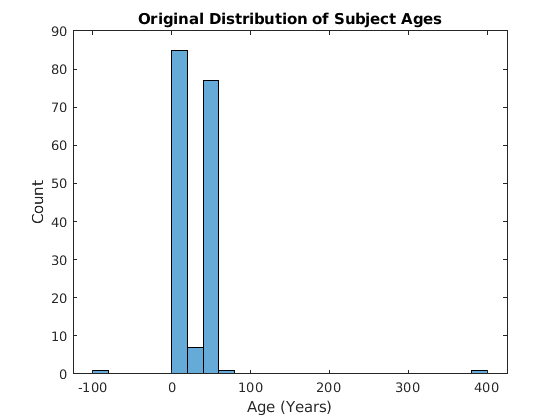

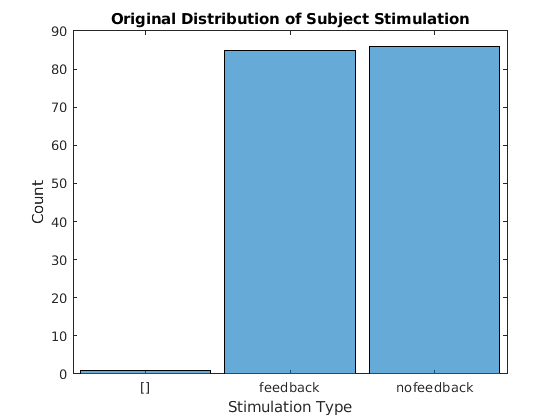

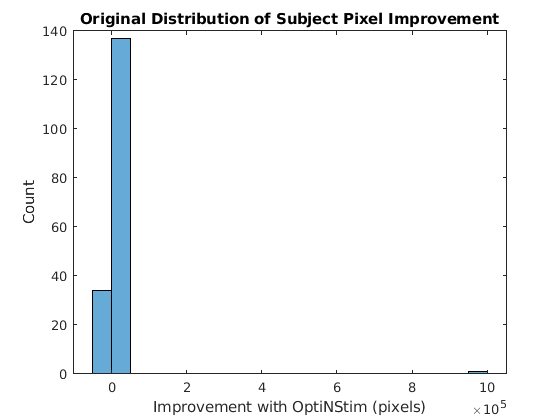

explore_dataset_with_histograms(original_data, "Original ")

**Age:** Most ages fall between 0-100, an expected human age distribution. Two values fall significantly outside of the expected range, -99 and 400, and do not look like realistic ages for participants in this study.

**Stimulation: T**here is a pretty even balance between given feedback and not given feedback. One value is empty.

**Pixels:** Most values are clustered together near 0. There is one value of 1000000 that is significantly bigger than the range of the 800 x 600 pixel screen. The maximum possible distance value of the display is the distance between the top corner and opposite bottom corner, which is 1000 pixels. Therefore the average pixel distance improvement after receiving OptiNStim should be less than 1000 pixels.

The values that were missing or out of possible range were probably the result of recording errors and those entries should be removed. We have a mid-sized to big dataset (173 samples) so removing missing or error type data instead of substituting their values is fine.

### Data Cleaning Procedure: Remove Missing and Obvious Outlier Data

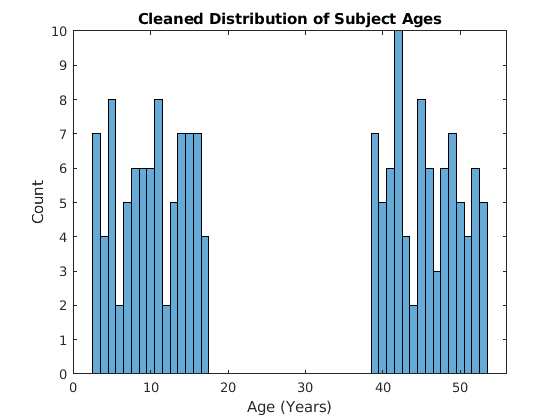

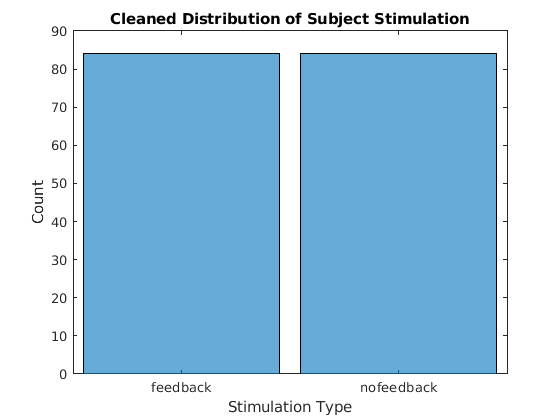

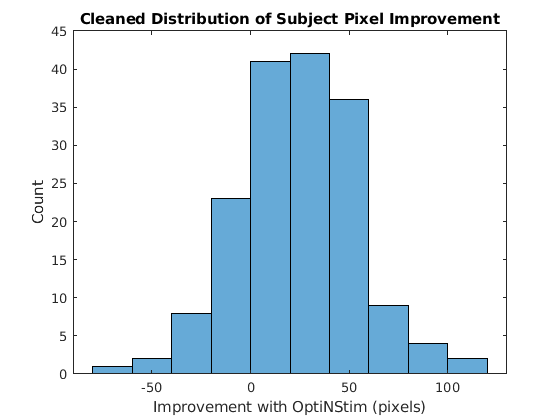

cleaned_data = original_data;
% clean Age
cleaned_data = cleaned_data(cleaned_data.Age > 0 & cleaned_data.Age < 100, :);
% clean Stimulation
cleaned_data = cleaned_data(cleaned_data.Stimulation ~= "[]", :);
cleaned_data.Stimulation = removecats(cleaned_data.Stimulation, "[]");
% clean Pixels
cleaned_data = cleaned_data(cleaned_data.Pixels < 1000, :);
explore_dataset_with_histograms(cleaned_data, "Cleaned ")

Since Age has a clear split between the ages of 2-17 (child) and 18+ (adult), turn Age into a categorical variable. This will make exploratory data analysis and ANOVA-testing for levels of categorical independent variables easier. While it is possible to analyze the data using a linear model with the value of age as a variable, it might be misleading to interpret a linear relationship with age, as we have no ages in the 18-40ish range.

cleaned_data.Age = discretize(cleaned_data.Age, [0 18 100], 'categorical', {'child', 'adult'});

Put all the combinations of factors into a table by Pixels value to make them easier to deal with.

feedback_child = table2array(cleaned_data(cleaned_data.Age == "child" & cleaned_data.Stimulation == "feedback", "Pixels"));
feedback_adult = table2array(cleaned_data(cleaned_data.Age == "adult" & cleaned_data.Stimulation == "feedback", "Pixels"));
nofeedback_child = table2array(cleaned_data(cleaned_data.Age == "child" & cleaned_data.Stimulation == "nofeedback", "Pixels"));
nofeedback_adult = table2array(cleaned_data(cleaned_data.Age == "adult" & cleaned_data.Stimulation == "nofeedback", "Pixels"));
ct = table(feedback_child, feedback_adult, nofeedback_child, nofeedback_adult);

## Hypothesis Testing with Two-Way ANOVA

### The Six Assumptions of Two-Way ANOVA test:

1. Independent variables each consist of two or more categorical, independent groups

2. Independence of Observations, no relationship between the observations in each group or between the groups themselves

3. Dependent variable should be measured at the continuous level

4. Dependent variable should be approximately normally distributed for each combination of the groups of the two independent variables

5. There needs to be homogeneity of variances for each combination of the groups of the two independent variables.

6. There should be no significant outliers

### Dataset's Adherence to the Six Assumptions of Two-Way ANOVA test:

**1. True. **

Independent variables are Stimulus and Age. 

- Stimulus is split into two categorical levels ("feedback", "nofeedback")

- Age is split into two categorical levels ("child", "adults")

**2. True.** Each observation is independent of all others.

**3. True.** Pixel improvements is a numerical, continuous value.

**4. True.** 

- Test for Normal Distribution using Lilliefors test. The result is 1 if the test rejects the null hypothesis that the data comes from a normal distribution at the 5% significance level, and 0 otherwise.

- P-values for all the combinations of groups fails to reject the null hypothesis.

assert(sum([ ...
    lillietest(ct.feedback_child), ...
    lillietest(ct.feedback_adult), ...
    lillietest(ct.nofeedback_child), ...
    lillietest(ct.nofeedback_adult) ...
    ]) == 0);

**5. True.**

- Test for homogeneity of variances for each combination of the groups of the two independent variables using Levene's test. Returns a summary table of statistics and a box-plot for the null hypothesis that the columns of data come from normal distributions with the same variance.

- With a p-value of 0.4468 the test fails to reject the null hypothesis at the 5% significance level.

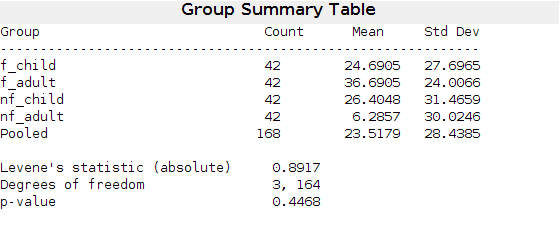

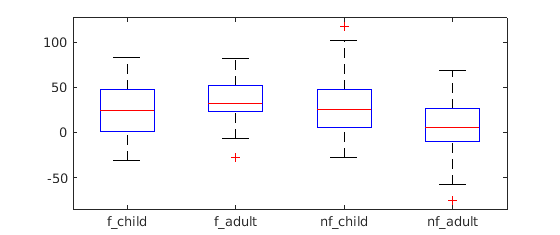

p = 0.4468

pixel_column = [
    ct.feedback_child;
    ct.feedback_adult;
    ct.nofeedback_child;
    ct.nofeedback_adult
    ];
groups = [
    repmat({'f_child'},size(ct.feedback_child, 1), 1);
    repmat({'f_adult'},size(ct.feedback_adult, 1), 1);
    repmat({'nf_child'},size(ct.nofeedback_child, 1), 1);
    repmat({'nf_adult'},size(ct.nofeedback_adult, 1), 1);
    ];
T = table(pixel_column, groups);
p = vartestn(T.pixel_column, T.groups, 'TestType',"LeveneAbsolute")

assert(p > 0.05)

**6. True.**

Outliers were filtered out in the previous steps.

See boxplots above. There are outliers based on boxplot's method of calculating outliers based on the interquartile range, but these outliers are located near the rest of the data, not isolated.

#### Check for Balanced Observation Counts

To perform a **Balanced Two-Way ANOVA test** the combinations should be evenly balanced.

gc = groupcounts(cleaned_data, {'Age', 'Stimulation'})

gc = 4×3 table
     Age     Stimulation    GroupCount
    _____    ___________    __________

    child    feedback           42    
    child    nofeedback         42    
    adult    feedback           42    
    adult    nofeedback         42    


assert(all(gc.GroupCount == gc.GroupCount(1)))
num_replications = gc.GroupCount(1)

num_replications = 42

The groups are balanced, with each combination of factors having 42 observations (i.e. the replication number is 42)

### Exploratory Data Analysis

#### Visually explore how means of factors-pairs compare to each other with Heatmap

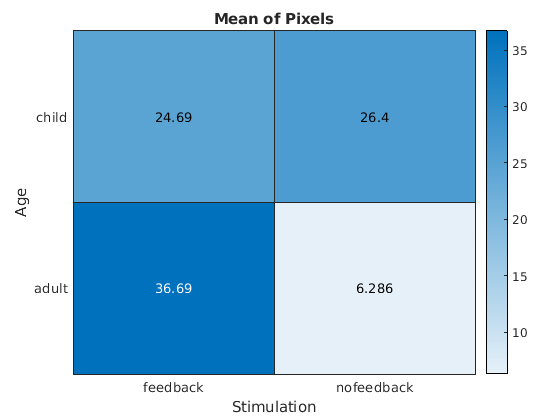

figure
heatmap(cleaned_data, 'Stimulation', 'Age', 'ColorVariable', 'Pixels', 'ColorMethod', 'mean')

This heatmap shows that

- On average, children perform about the same regardless of stimulus configurations

- On average, adults show a dramatic difference in performance for different stimulus configurations

- On average, children and adults have different performance given the OptiNStim

This heatmap DOES NOT show if the difference in performances for any of the factor pairs is significant enough, compared to the variance within the factor pairs, to reject the null hypotheses. To do that we must do a Two-Way ANOVA test.

#### Visually see where Pixel Improvement values for each group falls with Histograms

Represents variance information that is not captured by the heat-map and partially represented by box-plots. If the two distributions are separate, the effects of the variable may be significant.

We expect to see the biggest distribution difference between adult-feedback and adult-nofeedback based on the averages of the distributions (red vs. yellow).

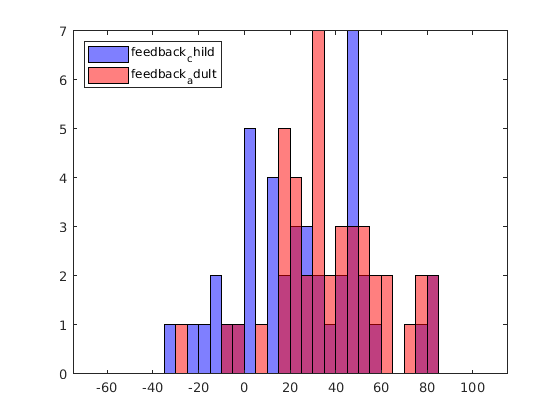

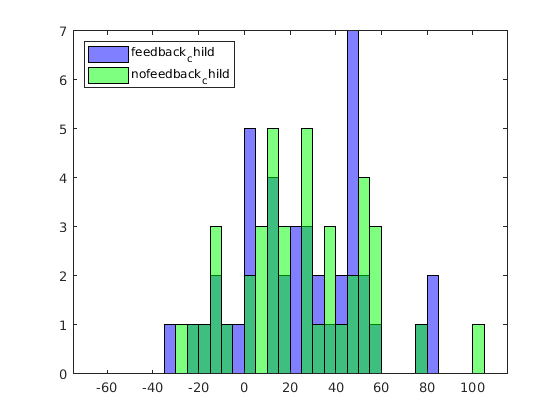

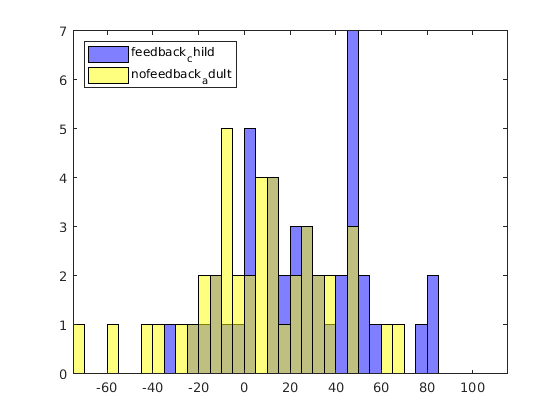

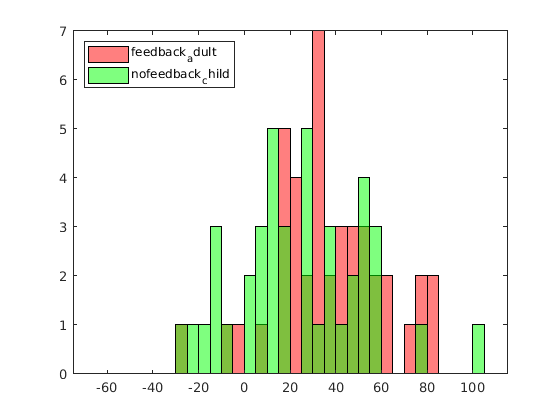

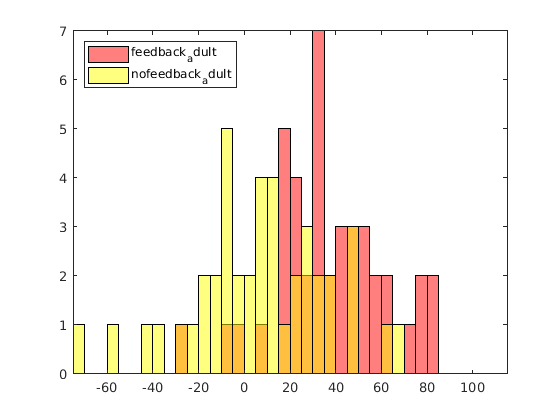

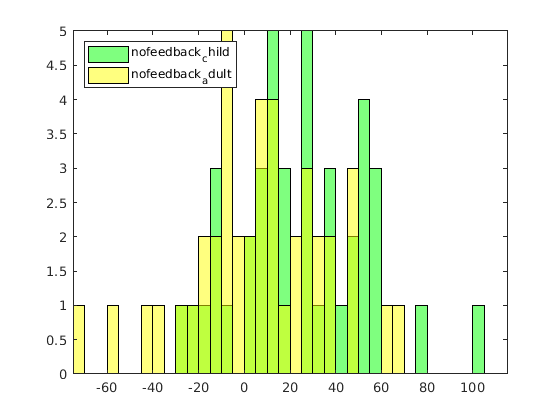

explore_combinations_with_histograms(ct, min(cleaned_data.Pixels), max(cleaned_data.Pixels), 5);

#### Data Preparation for MatLab's Two-Way ANOVA test:

Format the Pixel Improvement scores in matrix form

% first column is feedback, second column is nofeedback
% first 42 rows are child, next 42 rows are adult
pixel_matrix = [
    ct.feedback_child ct.feedback_adult;
    ct.nofeedback_child ct.nofeedback_adult
    ];

% check that the dimensions of the matrix are
% (num levels in factor 1 *replication number) x (num levels in factor 2)
size(pixel_matrix)

ans =     84     2


### Perform Balanced Two-Way ANOVA test

Perform a two-way analysis of variance (ANOVA) to see if there is any difference between the pixel value score of the age groups by sstimulus configuration.

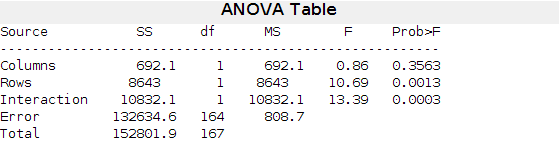

stats = struct with fields:
      source: 'anova2'
     sigmasq: 808.7478
    colmeans: [25.5476 21.4881]
        coln: 84
    rowmeans: [30.6905 16.3452]
        rown: 84
       inter: 1
        pval: 3.4003e-04
          df: 164


[~,~,stats] = anova2(pixel_matrix, num_replications)

## Two-Way ANOVA Test Interpretation:

% Bonferroni correction
corrected_alpha

corrected_alpha = 0.0250

**The p-val for the Age effect (Columns) is 0.3563**, which is *somewhat significant*. This result says that one of the age groups could be outperforming the other. The observed p-value indicates that an F-statistic as extreme as the observed F occurs by chance about 35 out of every 100 times. However, this is not low enough to reject H0_1.

**The p-val for the Stimulus effect (Rows) is 0.0013**, which is *highly significant.* This value indicates that one of the stimulus effects ("feedback" vs "nofeedback") leads to noticeably better performance than then other. **Thus we reject null hypothesis H0_2 at a significance level of 5%. We can also reject the null hypothesis H0_2 at a Bonferroni corrected significance level of 2.5%.**

**The p-value for Age and Stimulation interaction, 0.0003**, means that if there was no interaction, the observed result is *extremely unlikely* (3 out of 10000 times). This agrees with our exploratory data analysis finding that on average, adults have a strong performance change given different stimulus configurations, while children did not appear to have a strong performance change given one stimulus or another. **Thus we reject null hypothesis H0_3 at a significance level of 5%.  We can also reject the null hypothesis H0_2 at a Bonferroni corrected significance level of 2.5%.**

## **Follow-Up Tests**

`multcompare` displays the estimates with  comparison intervals around them.

### For Age Group

I perform a multiple test to see if the pixel performance differs between the compared groups of age. There is not a significant difference in means.

Note: Your model includes an interaction term that is significant at the level 
you specified. Testing main effects under these conditions is questionable.


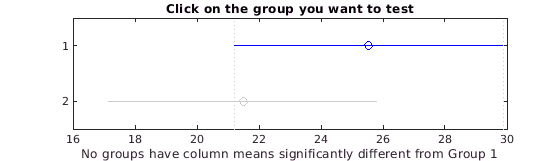

c =     1.0000    2.0000   -4.6050    4.0595   12.7241    0.3563


m =    25.5476    3.1029
   21.4881    3.1029


h =   Figure (18: Multiple comparison of column means) with properties:

      Number: 18
        Name: 'Multiple comparison of column means'
       Color: [0.9400 0.9400 0.9400]
    Position: [681 818.4000 560 160.6000]
       Units: 'pixels'

  Show all properties


gnames = 2×1 char array
    '1'
    '2'


[c, m, h, gnames] = multcompare(stats, 'Alpha',0.05,'CType','bonferroni')

### For Stimulus Configuration

I perform a multiple test to see if the pixel performance differs between the compared stimulus configurations. There is a significant difference in means.

Note: Your model includes an interaction term that is significant at the level 
you specified. Testing main effects under these conditions is questionable.


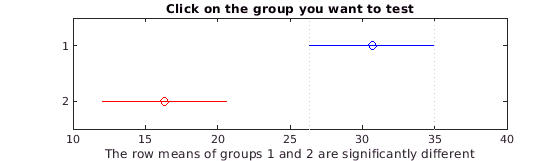

c =     1.0000    2.0000    5.6807   14.3452   23.0098    0.0013


m =    30.6905    3.1029
   16.3452    3.1029


h =   Figure (18: Multiple comparison of row means) with properties:

      Number: 18
        Name: 'Multiple comparison of row means'
       Color: [0.9400 0.9400 0.9400]
    Position: [681 818.4000 560 160.6000]
       Units: 'pixels'

  Show all properties


gnames = 2×1 char array
    '1'
    '2'


[c, m, h, gnames] = multcompare(stats, 'Estimate', 'row', 'Alpha',0.05,'CType','bonferroni')

## **Evaluation of Effect Size**

Eta squared can be calculated directly from the results of the ANOVA test. Effect size is an indictor to how big the effect of a statistically significant value is in a population.

ETA_sq = SS_effect / SS_total

SS_total = stats(6, 2);
SS_total = SS_total{1};
ETA_sq_age = stats(2, 2);
ETA_sq_age = ETA_sq_age{1} / SS_total
ETA_sq_stimulation = stats(3, 2);
ETA_sq_stimulation = ETA_sq_stimulation{1} / SS_total
ETA_interaction = stats(4, 2);

ETA_sq_age = 0.0045

ETA_interaction = ETA_interaction{1} / SS_total

The results of the eta squared test say that:

- 0.45% of the variance is associated with age group

- 5.66% of the variance is associated with stimulus configuration

- 7.09% of the variance is associated with the interaction of age and stimulus

All of these effect sizes are smaller than Cohen's benchmark of 0.1, and are therefore likely too small to discern.

## Conclusion:

The dataset met all the assumptions for performing a **balanced Two-Way ANOVA **test with 42 observations for each combination of factors.

The results of the ANOVA test allowed us to:

- reject null hypothesis H0_2, that Stimulus Configuration has no significant effect on pixel improvement at a significance level of 2.5% 

- reject null hypothesis H0_3, the factors of Stimulus Configuration and Age Group are independent, at a significance level of 2.5%

The multiple comparisons test confimed that Age Group had no significant difference in effect, but Stimulus Configuration did have an effect. However, since there is a significant interaction effect, testing main conditions in this was may be questionable.

The effect sizes found by eta squared formula are

- 5.66% of the variance is associated with stimulus configuration

- 7.09% of the variance is associated with the interaction of age and stimulus

These effect sizes were very small and will not have a meaningful effect on the population at large.

## References:

- MatLab Documentation

- Six Assumptions of Two-Way ANOVA testing: [https://statistics.laerd.com/spss-tutorials/two-way-anova-using-spss-statistics.php](https://statistics.laerd.com/spss-tutorials/two-way-anova-using-spss-statistics.php)

### Plotting Helper Functions

function [] = plot_histogram(data, title_label, x_label, y_label)

ETA_sq_stimulation = 0.0566

    figure
    histogram(data);

ETA_interaction = 0.0709

    title(title_label)
    xlabel(x_label)
    ylabel(y_label)
end

function [] = explore_dataset_with_histograms(data, modifier)
    plot_histogram(data.Age, modifier + "Distribution of Subject Ages", "Age (Years)", "Count");
    plot_histogram(data.Stimulation, modifier + "Distribution of Subject Stimulation", "Stimulation Type", "Count");
    plot_histogram(data.Pixels, modifier + "Distribution of Subject Pixel Improvement", "Improvement with OptiNStim (pixels)", "Count");
end

function [] = explore_combinations_with_histograms(ct, min_range, max_range, interval)
    xrange = min_range:interval:max_range;
    colorMap = containers.Map(ct.Properties.VariableNames, {'blue', 'red', 'green', 'yellow'});
    for i = 1:4
        name1 = ct.Properties.VariableNames(i);
        color1 = values(colorMap,name1);
        for j = i+1:4
            figure
            name2 = ct.Properties.VariableNames(j);
            color2 = values(colorMap,name2);
            histogram(ct{:,i}, xrange, 'FaceColor', color1{1}, 'FaceAlpha', 0.5);
            hold on
            histogram(ct{:,j}, xrange, 'FaceColor', color2{1}, 'FaceAlpha', 0.5);
            legend(name1{1}, name2{1}, 'Location', 'northwest')
            hold off
            axis tight
        end
    end
end